clear;

M = 264.5866;
m = 9.1747;
l = 2.5849;
g = 9.81;

A = [0, 1, 0, 0;
    0, 0, (3*g*m)/(m+4*M), 0;
    0, 0, 0, 1;
    0, 0, (6*g*(m+M))/(l*(m+4*M)), 0]

A =          0    1.0000         0         0
         0         0    0.2529         0
         0         0         0    1.0000
         0         0    5.8395         0



B = [0; 4/(m+4*M); 0; 6/(l*(m+4*M))];
C = [1, 0, 0, 0; 0, 0, 1, 0];
D = [0; 6/(l*(m+4*M)); 0; (12*(m+M))/(l^2*m*(m+4*M))];

% Регулятор модальный (пункт 3.2)
Gamma_r = [-10 0 0 0; 0 -20 0 0; 0 0 -30 -10; 0 0 10 -30];
Y_r = [1 1 1 1];

cvx_begin sdp

variable P_r(4, 4)
A*P_r-P_r*Gamma_r == B*Y_r;

cvx_end

Homogeneous problem detected; solution determined analytically.
Status: Solved
Optimal value (cvx_optval): +0
 


A*P_r;
P_r;
det(P_r);
K = -Y_r*pinv(P_r)

K = 1.0e+07 *

    0.9376    0.1969   -1.7540   -0.3435



eig(A+B*K)

ans =  -30.0000 +10.0000i
 -30.0000 -10.0000i
 -20.0000 + 0.0000i
 -10.0000 + 0.0000i




x_07 = [0.01; 0.01; 0.01; 0.01];
x_0 = x_07;
f = 0;
 
tspan = [0 0.7];
% Решение ОДУ
[t, x] = ode45(@(t,x) pendulum_ode(t,x,K,f,m,M,l,g), tspan, x_0);

u = zeros(length(t), 1);
for i = 1:length(t)
    [~, u_i] = pendulum_ode(t(i), x(i, :)', K, f, m, M, l, g);
    u(i) = u_i;
end

%plot(t, u);
disp('phi');

phi


max_phi = max(x(:,3))

max_phi = 0.0162

min(x(:,3))

ans = -0.0499


disp('a');

a


max_a = max(x(:,1))

max_a = 0.0251

min(x(:,1))

ans = -0.0935


disp('u')

u


max_u = max(u)

max_u = 2.2996e+04

min(u)

ans = -9.6295e+04

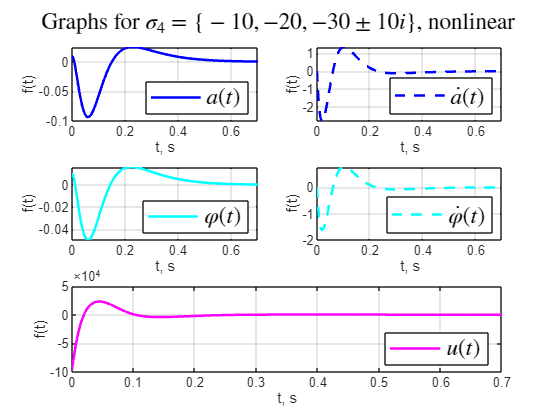



% Графики
%figure('Position', [100 100 800 400])
subplot(3,2,1);
plot(t, x(:,1), 'b-', 'LineWidth',1.5); 
legend('$a(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.7])
grid()

%figure('Position', [100 100 800 400])
subplot(3,2,2);
plot(t, x(:,2), 'b--', 'LineWidth',1.5); 
legend('$\dot{a}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.7])
grid()

subplot(3,2,3);
plot(t, x(:,3), 'c-', 'LineWidth',1.5); 
legend('$\varphi (t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.7])
grid()

subplot(3,2,4);
plot(t, x(:, 4), 'c--', 'LineWidth',1.5);
legend('$\dot{\varphi}(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
xlim([0 0.7])
grid()

subplot(3,2,[5 6]);
plot(t, u, 'm-', 'LineWidth',1.5);
legend('$u(t)$','Interpreter','latex',  'FontSize', 14, 'Location', 'southeast')
ylabel('f(t)')
xlabel('t, s')
%xlim([0 7])
grid()


sgtitle('Graphs for $\sigma_4 = \{ -10, -20, -30 \pm 10i\}$, nonlinear','Interpreter','latex',  'FontSize', 14)
full_path = ['C:\Users\user\Desktop\STUDY_2.0\3 курс робототехника\6 семестр\ТАУ\TAU_\1_Course_Project\' ...
    'pic_fix\3_x_nlin_s4.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);